# Investigating the dimensionless version of parameter A

In the article **Control of Hamiltonian chaos as a possible tool to control anomalous transport in fusion plasmas (Ciraolo, Pettini et al., PHYSICAL REVIEW E 69, 056213 (2004))**, the electrostatic potential (it could be expressed in Volts) is:

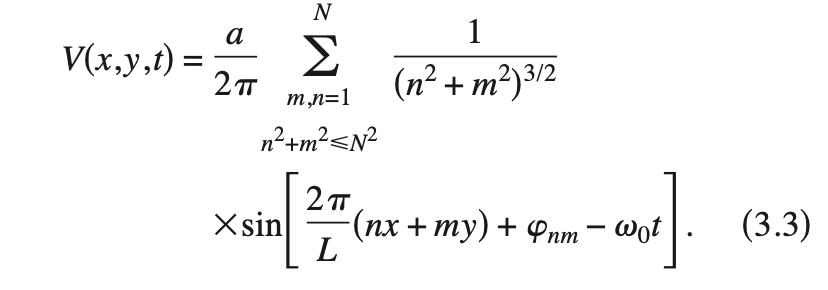

If we consider $a = 2\pi$ (it could very well be a different value) and $\omega_0 =\frac{2\pi }{\tau \;}$ (this is a definition), then the potential has the same form as the one used in our work (different symbols are used, but it is easy to see what symbolic changes have been made):

$\Phi(x,y,t)= 1 \cdot \sum_{{n,m=1; n^2+m^2\leq M^2}}^M \frac{1}{(n^2+m^2)^{3/2}} \sin\bigg(\frac{2\pi}{\lambda}(n x +m y) + \varphi_{nm} -\frac{2\pi}{\tau}t\bigg) [V]$.

This is a general form, through which a real turbulent potential is modelled by assuming a series of sines of spatial period $\lambda$ and temporal period $\tau$, with the effect of turbulence obtained by using random phases $\varphi_{nm}$. 

In our code, however, the potential, other than being multiplied by $A=\varepsilon_\delta /B$ so that$\phi(x,y,t)=A\Phi(x,y,t)$, and other than being modified into a guiding-center potential ($\phi(x,y,t) \rightarrow \psi(X,Y,t)$), has fixed spatial and temporal periods of $2\pi$. This last aspect can be achived by conveniently rescaling the spatial coordinates of the transverse plane and time:


$$\hat x = \frac{2\pi x}{\lambda} [\#]$$



$$\hat y = \frac{2\pi y}{\lambda} [\#]$$



$$\hat t = \frac{2\pi t}{\tau} [\#]$$


This leads to the form of the potential which is closely related to the one treated by our Python code:

$\hat \Phi(x,y,t)= \sum_{{n,m=1; n^2+m^2\leq M^2}}^M \frac{1}{(n^2+m^2)^{3/2}} \sin\bigg((n \hat x +m \hat y) + \varphi_{nm} - \hat t\bigg) [\#]$.

The fixed periodicities of $2\pi$ of this dimensionless potential are preserved while moving to the dimensionless versions of $\phi (\text{originally in } [V/T])$ or $\psi (\text{originally in }[V/T]$. This last one is the one implemented in Python for the PDEs governing the dynamics of guiding-centers.

An interesting aspect of $\Phi$ and $\hat \Phi$ is that their ratio is equal to 1. In explicit:

$\frac{\Phi(x,y,t)}{\hat \Phi(\hat x, \hat y, \hat t)} = 1 [V]$.

This aspect comes from the fact that, by moving from the dimensional potential to the dimensionless one, only the argument of the sine have been treated. Nothing has been outside the trigonometric function to move from Volts/Meters to a dimensionless quantity. However, in order to highlight that a dimensionless procedure has been used, it is useful to give a name to the ratio between the two potentials:

$\Phi_0 = \frac{\Phi(x,y,t)}{\hat \Phi(\hat x, \hat y, \hat t)} = 1 [V]$.

It can be seen that it is 1 for the particular case assumed here, that is $a = 2\pi$ in the very first equation. If, for example, $a = 1$, then this same ratio would have a different value:

$\Phi_0 = \frac{\Phi(x,y,t)}{\hat \Phi(\hat x, \hat y, \hat t)} = \frac{a}{2\pi} [V]$.

By reasoning on the equations of motion it is possible to establish other relations involving also the intensity of the actual magnetic field, as it was shown in the reports of both Stanzani and Arlotti.

$\hat B = \frac{B}{B_0} [\#]$,

$B_0 = \frac{2\pi \tau}{\lambda^2}\Phi_0 \text{  }[T]$.

The thing now is that, if the ratio between the potentials if fixed and it is equal to 1, then all of a sudden also $B_0$, which is a rescaling factor for the actual amplitude of the magnetic field $B$, is fixed by the characteristics of the actual electrostatic potential of the fusion device (modelled through sines of periods $\lambda$ and $\tau$). In other words, if $\lambda$, $\tau$ and $B$ are known (and in theory they can be obtained or derived from real measurements), then $B_0$ and $\phi_0$ are fixed quantities, which should not be arbitrarily chosen. In particular:

$\Phi_0 = 1 [V]$,

$B_0 = 1 \cdot \frac{2\pi \tau}{\lambda^2} \text{  }[T]$.

% [.]_ = dimensionless version of [.]
rho_m = 0.007      % m

rho_m = 0.0070

larmor_freq_MHz = 0.5 % MHz

larmor_freq_MHz = 0.5000

eta_s = 1 / (2*larmor_freq_MHz*10^6)     % s

eta_s = 1.0000e-06

rho_cm = rho_m*100

rho_cm = 0.7000

rho_mm = rho_m*1000

rho_mm = 7

lambda_m = 0.015   % m

lambda_m = 0.0150

freq_Hz = 750        % Hz

freq_Hz = 750

tau_s = 1/freq_Hz                           % s

tau_s = 0.0013

eps_adim = 0.05    % adim.

eps_adim = 0.0500

Phi_V = 1000       %V

Phi_V = 1000

B_T = 2.7          %T

B_T = 2.7000


% -----------------------------
a = 2*pi                              %(Eq. (3.3) in Pettini et al.)

a = 6.2832

Phi0_V = a / (2*pi)                   % V

Phi0_V = 1

B0_T = Phi0_V*2*pi*tau_s/(lambda_m^2) % T

B0_T = 37.2337

rho_adim = rho_m*2*pi/lambda_m        % adim. 

rho_adim = 2.9322

eta_adim = eta_s*2*pi/tau_s           % adim.

eta_adim = 0.0047

B_adim = B_T/B0_T                     % adim.

B_adim = 0.0725

A_adim = eps_adim/B_adim              % adim.

A_adim = 0.6895

Phi_adim = Phi_V/Phi0_V               % adim.

Phi_adim = 1000

phi_adim = A_adim*Phi_adim            % adim.

phi_adim = 689.5128


% -----------------------------
% % Parameters
% N = 50;
% M = 25; % Maximum value for n and m
% [x, y] = meshgrid(0:(lambda/N):lambda); % Grid points for x and y
% [x_, y_] = meshgrid(0:(2*pi/N):2*pi);
% t = 0; % Time
% t_ = 2*pi*t/tau;
% Phi = zeros(size(x));
% Phi_ = zeros(size(x));
% 
% % Calcolo del potenziale
% for n = 1:M
%     for m = 1:M
%         if n^2 + m^2 <= M^2
%             r = rand;
%             Phi = Phi + 1 ./ ((n^2 + m^2)^(3/2)) .* sin(2*pi/lambda * (n * x + m * y) + r * 2 * pi - 2*pi*t/tau);
%             Phi_ = Phi_ + 1 ./ ((n^2 + m^2)^(3/2)) .* sin(n * x_ + m * y_ + r * 2 * pi - t_);
%         end
%     end
% end
% 
% phi = A*Phi;
% phi_ = A_*Phi_;
% mean_Phi_ratio = mean(mean(Phi./Phi_))
% 
% % % Plot
% % figure;
% % contourf(x, y, Phi);
% % colorbar
% % xlabel('x adim.');
% % ylabel('y adim.');
% % title('Potenziale \Phi(x,y,t)');
% % 
% % % Plot
% % figure;
% % contourf(x, y, phi);
% % colorbar
% % xlabel('x');
% % ylabel('y');
% % title('Potenziale \phi(x,y,t)');
% % 
% % 
% % figure;
% % contourf(x_, y_, Phi_);
% % colorbar
% % xlabel('x adim.');
% % ylabel('y adim.');
% % title('Potenziale adimensionale \Phi(x,y,t)');
% % 
% % figure;
% % contourf(x_, y_, phi_);
% % colorbar
% % xlabel('x adim.');
% % ylabel('y adim.');
% % title('Potenziale adimensionale \phi(x,y,t)');